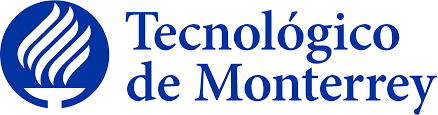

### Fundamentación de robótica (TE3001B)

## Actividad 1 (Velocidades Lineales y angulares)

### Pamela Hernández Montero A01736368

**Objetivo**

Usar Matlab para el cálculo de velocidades angulares y lineales de un robot de 2 grados de libertad (2gdl).

**Introducción**

La cinemática es una rama de la física que se encarga de estudiar el movimiento de los objetos, sin considerar las causas que lo producen. En el contexto de los robots de 2dgl, la cinemática se utiliza para describir y predecir cómo se moverá el robot en función de sus características geométricas y de diseño. En este trabajo se obtiene el vector de velocidades lineal y angular para la siguiente configuración:

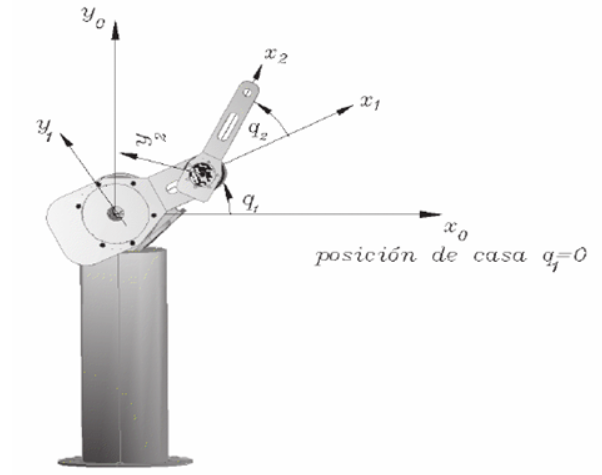

Antes de comenzar con la codificacion es importante estudiar el diseño del robot:

En este caso $z_0$ del sistema de origen ($y_0$, $x_0$ y $z_0$) coincide perpendicularmente con el valor del primer eslabón $z_1$ dando así el primer grado de libertad.

Primer Grado de Libertad (GDL):

- El primer eslabón está conectado a una base fija mediante una articulación que permite girar en torno al eje z.

- El plano de este grado de libertad se encuentra en ,  

Segundo Grado de Libertad (GDL):

- El segundo eslabón está conectado al extremo del primer eslabón mediante una segunda articulación.

- Esta articulación usa una junta rotacional por lo que $z_0$, $z_1$ y $z_3$ son perpendiculares.

Si observamos el movimiento del robot se puede deducir que solo trabaja en el plano XY y gira alrededor de z.

%Limpieza de pantalla
clear all
close all
clc

Para poder calcular la velocidad angular y lineal es necesario declarar las variables simbólicas apropiadas. Estas variables simbólicas se utilizan para representar cantidades que pueden variar en términos de otras variables, permitiendo así realizar cálculos simbólicos en lugar de numéricos. En este caso  `q1(t)` y `q2(t)` representan las posiciones angulares (θ) en función del tiempo función del tiempo `t` mientras que las variables `l1` y `l2` representan las longitudes de los eslabones del robot correspondientes a cada una de las articulaciones `q1` y `q2` respectivamente.

% Declaración de las variables simbólicas
syms q1(t) l1 t q2(t) l2

El vector `RP = [0 0];` indica que las dos juntas del robot son del tipo rotacional, lo que significa que el movimiento de los eslabones del robot se realiza mediante juntas que permiten el movimiento de rotación en este caso en `z`.

Es importante tener en cuenta las características de cada tipo de junta:

- Las juntas rotacionales permiten el movimiento de rotación alrededor de un eje específico.

- Las juntas prismáticas permiten el movimiento lineal o de traslación a lo largo de un eje específico.

% Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP = [0 0];

El vector `Q` contiene las coordenadas articulares del sistema representando las posiciones angulares de sus articulaciones. Mientras que el vector `Qp` contiene las velocidades articulares que representan la velocidad de cambio de las coordenadas articulares con respecto al tiempo.

% Creamos el vector de coordenadas articulares
Q = [q1 q2];
disp("Coordenadas articulares"); pretty(Q);

Coordenadas articulares
(q1(t), q2(t))



% Creamos el vector de velocidades articulares
Qp = diff(Q, t);
disp("Velocidades articulares "); pretty(Qp);

Velocidades articulares 
/  d         d       \
| -- q1(t), -- q2(t) |
\ dt        dt       /



Las velocidades articulares se relacionan con las derivadas de `q1(t)` y `q2(t)` debido que el cambio en las posiciones angulares de las articulaciones afecta directamente las velocidades de las mismas.

Por otro lado se determina el número de columnas en la matriz RP. Dado que cada columna representa una junta del robot, este valor es igual al número de juntas y, por lo tanto, al número de GDL del robot. Para facilitar su uso, el número de GDL se convierte en una cadena de caracteres mediante la función num2str(GDL) y se almacena en la variable GDL_str.

% Número de grado de libertad del robot
GDL = size(RP, 2);
GDL_str = num2str(GDL);

Para encontrar las velocidades angulares y lineales, se utilizan las matrices de transformación homogéneas. Estas matrices describen cómo se relacionan las diferentes partes del robot entre sí y con el sistema de coordenadas global.

Una vez que se han calculado las matrices de transformación homogéneas para todas las articulaciones, se utilizan para determinar la posición y orientación del robot, además, al derivar estas matrices con respecto al tiempo, se obtiene las velocidades angulares y lineales.Lo primero consiste en definir la posición de las articulaciones del robot. 

La posición de la articulación 1 se calcula utilizando la longitud `l1` del primer eslabón del robot y el ángulo `q1` que representa la posición angular de la articulación 1. Esta posición se define como un vector en coordenadas cartesianas [x, y, z], donde las componentes x e y se calculan como `l1*cos(q1)` y `l1*sin(q1)` respectivamente, y la componente z se establece en 0 ya que asumimos un movimiento plano.

Por otro lado, la posición de la articulación 2 se define en función de la posición de la articulación 1 y la longitud `l2` del segundo eslabón del robot, junto con el ángulo `q2` que representa la posición angular de la articulación 2. Similarmente a la articulación 1, las componentes x e y se calculan como `l2*cos(q1 + q2)` y `l2*sin(q1 + q2)` respectivamente, mientras que la componente z se mantiene en 0 debido al movimiento plano.

% Articulación 1
% Definición de la posición de las articulaciones
P(:,:,1) = [l1*cos(q1); 
            l1*sin(q1); 0]; % Posición de la junta 1 respecto al origen
P(:,:,2) = [l2*cos(q2);
            l2*sin(q2);0]; % Posición de la junta 2 respecto a la junta 1

Se agregan las matrices de rotación para definir las orientaciones de las articulaciones del robot.

% Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1) = [cos(q1) -sin(q1) 0;
            sin(q1) cos(q1)  0;
            0          0     1];
%Matriz de rotación de la articulación 2 respecto a 1
R(:,:,2) = [cos(q2) -sin(q2) 0;
            sin(q2)  cos(q2) 0;
            0        0       1];

Después de definir las matrices de rotación y las posiciones de las articulaciones, se procede a inicializar las matrices de transformación homogéneas locales y globales. Esto implica crear un vector de ceros, que se utilizará para completar la cuarta fila de las matrices de transformación homogéneas. Luego, se inicializan las matrices de transformación homogéneas locales y globales para la última articulación del robot utilizando las matrices de rotación y las posiciones correspondientes. 

% Creamos un vector de ceros
Vector_zeros = zeros(1, 3);

% Inicializamos las matrices de transformación homogéneas locales
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_zeros 1]);

% Inicializamos las matrices de transformación homogénea locales
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_zeros 1]);

En el vector PO se guarda la posición de la última articulación del robot en relación con el sistema de coordenadas global, mientras que en el vector de rotación (RO) se  almacena la orientación de la última articulación del robot en relación con el sistema de coordenadas global.

% Inicializamos los vectores de posición y rotacion
PO(:,:,GDL) = P(:,:,GDL);
RO(:,:,GDL) = R(:,:,GDL);

El bucle `for` itera sobre todas las articulaciones del robot, para calcular tanto las matrices de transformación locales como globales y extraer la información relevante de estas matrices.

for i = 1:GDL
    i_str = num2str(i);
    % Locales 
    disp(strcat("Matriz de transformación local A", i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_zeros 1]);
    pretty(A(:,:,i));
    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i);
    end
    disp(strcat("Matriz de transformación global T", i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));
    % Obtenemos la matriz de rotación "RO" y el vector de translación PO de
    % la matriz de transformación homogénea global T(:,:,GDL)
    RO(:,:,i) = T(1:3, 1:3, i);
    PO(:,:,i) = T(1:3, 4, i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i))
end

Matriz de transformación local A1


/ cos(q1(t)), -sin(q1(t)), 0, l1 cos(q1(t)) \
|                                           |
| sin(q1(t)),  cos(q1(t)), 0, l1 sin(q1(t)) |
|                                           |
|      0,          0,      1,       0       |
|                                           |
\      0,          0,      0,       1       /



Matriz de transformación global T1


/ cos(q1(t)), -sin(q1(t)), 0, l1 cos(q1(t)) \
|                                           |
| sin(q1(t)),  cos(q1(t)), 0, l1 sin(q1(t)) |
|                                           |
|      0,          0,      1,       0       |
|                                           |
\      0,          0,      0,       1       /



/ cos(q1(t)), -sin(q1(t)), 0 \
|                            |
| sin(q1(t)),  cos(q1(t)), 0 |
|                            |
\      0,          0,      1 /



/ l1 cos(q1(t)) \
|               |
| l1 sin(q1(t)) |
|               |
\       0       /



Matriz de transformación local A2


/ cos(q2(t)), -sin(q2(t)), 0, l2 cos(q2(t)) \
|                                           |
| sin(q2(t)),  cos(q2(t)), 0, l2 sin(q2(t)) |
|                                           |
|      0,          0,      1,       0       |
|                                           |
\      0,          0,      0,       1       /



Matriz de transformación global T2


/ #2, -#1, 0, l1 cos(q1(t)) + l2 #2 \
|                                   |
| #1,  #2, 0, l1 sin(q1(t)) + l2 #1 |
|                                   |
|  0,  0,  1,           0           |
|                                   |
\  0,  0,  0,           1           /

where

   #1 == sin(q1(t) + q2(t))

   #2 == cos(q1(t) + q2(t))




/ cos(q1(t) + q2(t)), -sin(q1(t) + q2(t)), 0 \
|                                            |
| sin(q1(t) + q2(t)),  cos(q1(t) + q2(t)), 0 |
|                                            |
\          0,                  0,          1 /



/ l1 cos(q1(t)) + l2 cos(q1(t) + q2(t)) \
|                                       |
| l1 sin(q1(t)) + l2 sin(q1(t) + q2(t)) |
|                                       |
\                   0                   /



Matriz de transformación local y global de articulación 1:

- Indica que hay una rotación alrededor del eje z.

- Ambas son iguales debido a que considera el origen y el primer eslabón.

- Su angulo solo depende de su propio ángulo q1

Matriz de transformación local y global de articulación 2:

- Indica que hay una alrededor del eje z.

- Las matrices A2 y T2 son diferentes debido a que la articulación 2 está afectada tanto por su propio ángulo q2 como por el ángulo de la articulación q1.

Como se explicó anteriormente ambas articulaciones tienen el mismo movimiento es por ello que las matrices de transformación local A1 y A2 son iguales.

Posterior a ello se calcula el Jacobiano lineal (por el método diferencial y analitico solo para comprobación) y angular. Mientras que el Jacobiano lineal relaciona las velocidades lineales de los puntos en el sistema de coordenadas, el Jacobiano angular relaciona las velocidades angulares de los ejes de rotación.

Las siguientes líneas calculan el Jacobiano lineal de forma diferencial para ello se calculan las derivadas parciales de las coordenadas x, y y z del vector de posición con respecto a la velocidad angular de cada angulo haciendo uso de la función "functionalDerivative" de Matlab.

% Calculamos el jacobiano lineal de forma diferencial

% Derivadas parciales de x respecto a q1
Jv11 = functionalDerivative(PO(1, 1, GDL), q1);
Jv12 = functionalDerivative(PO(1, 1, GDL), q2);
% Derivadas parciales de y respecto a q1
Jv21 = functionalDerivative(PO(2, 1, GDL), q1);
Jv22 = functionalDerivative(PO(2, 1, GDL), q2);
% Derivadas parciales de z respecto a q1
Jv31 = functionalDerivative(PO(3, 1, GDL), q1);
Jv32 = functionalDerivative(PO(3, 1, GDL), q2);
% Creamos la matriz del jacobiano lineal
jv_d = simplify([Jv11 Jv12; Jv21 Jv22; Jv31 Jv32]);
disp("Jacobiano lineal obtenido de forma diferencial"); pretty(jv_d)

Jacobiano lineal obtenido de forma diferencial
/ - l1 sin(q1(t)) - l2 sin(q1(t) + q2(t)), -l2 sin(q1(t) + q2(t)) \
|                                                                 |
|  l1 cos(q1(t)) + l2 cos(q1(t) + q2(t)),   l2 cos(q1(t) + q2(t)) |
|                                                                 |
\                    0,                               0           /



Para obtener el Jacobiano lineal de forma analítica se considera calcular el producto cruz entre la tercera columna de la matriz de rotación y la resta entre la posición final y la anterior.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    
Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp("Jacobiano lineal obtenido de forma analítica"); pretty(Jv_a);

Jacobiano lineal obtenido de forma analítica
/ - l1 sin(q1(t)) - l2 sin(q1(t) + q2(t)), -l2 sin(q1(t) + q2(t)) \
|                                                                 |
|  l1 cos(q1(t)) + l2 cos(q1(t) + q2(t)),   l2 cos(q1(t) + q2(t)) |
|                                                                 |
\                    0,                               0           /



Como se puede observar ambas matrices jacobianas (metodo analitico y diferencial) son iguales denotando que el procedimiento para calcularlas fue correcto.

disp("Jacobiano angular obtenido de forma analítica");pretty(Jw_a);

Jacobiano angular obtenido de forma analítica
/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /



Por ultimo se obtiene jacobiano angular, ahora para calcular la velocidad lineal del sistema se multiplica el jacobiano lineal por la matriz de velocidades articulares, mientras que para calcular la velocidad angular se multiplica el jacobiano angular y la matriz de velocidades articulares.

V =  simplify(Jv_a*Qp');
disp("Velocidad lineal obtenida mediante el Jacobiano lineal"); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/   ________                              ________    \
|    d                                     d          |
| - -- q1(t) (l1 sin(q1(t)) + l2 #1) - l2 -- q2(t) #1 |
|   dt                                    dt          |
|                                                     |
|  ________                              ________     |
|   d                                     d           |
|  -- q1(t) (l1 cos(q1(t)) + l2 #2) + l2 -- q2(t) #2  |
|  dt                                    dt           |
|                                                     |
\                          0                          /

where

   #1 == sin(q1(t) + q2(t))

   #2 == cos(q1(t) + q2(t))




W = simplify(Jw_a*Qp');
disp("Velocidad angular mediante el Jacobiano angular"); pretty(W);

Velocidad angular mediante el Jacobiano angular
/          0          \
|                     |
|          0          |
|                     |
| ________   ________ |
|  d          d       |
| -- q1(t) + -- q2(t) |
\ dt         dt       /



Las velocidades lineales indican que existe movimiento en los ejes x y y, mientras que el movimiento en el eje z se mantiene en cero, lo que significa que no hay velocidad lineal en la dirección z. Por otro lado al examinar las velocidades angulares, se observa que no hay velocidad angular en los ejes x y y, pero sí en el eje z. Esta velocidad angular en el eje z es la suma de las derivadas respecto al tiempo de las posiciones angulares de las articulaciones en función del tiempo.